# Linear algebra

Scalars, vectors and 2nd-order tensors are the most essential mathematical objects in Anakin. The class `tensor` allows creating them.

Start by importing the Anakin framework into Matlab. Be sure to include Anakin's base directory before you run this line:

import anakin.*

## Object creation

The default tensor is the null scalar:

v = tensor % default call

v = Scalar with value:
     0


Scalars are created by passing the value to the constructor:

E = tensor(25) % example of scalar

E = Scalar with value:
    25


Vectors can be created by passing their canonical components. Regardless of the shape of the input, the object stores the components in column form:

a = tensor([4;5;6]) % as a column vector

a = Vector with components:
     4
     5
     6


b = tensor([7,8,9]) % as a row vector

b = Vector with components:
     7
     8
     9


Similarly, one can create 2nd order tensors by giving their canonical component matrix:

T = tensor([1,2,3;4,5,6;7,8,9])

T = Second-order tensor with components:
     1     2     3
     4     5     6
     7     8     9


Tensors and vectors can be given in another basis. Internally, the object stores only its components in the canonical basis:

B1 = basis([1;0;0],[0;cos(pi/6);sin(pi/6)],[0;-sin(pi/6);cos(pi/6)]);

a = tensor([0;1;0],B1) 

a = Vector with components:
         0
    0.8660
    0.5000


T = tensor([1,2,3;4,5,6;7,8,9],B1) 

T = Second-order tensor with components:
    1.0000    0.2321    3.5981
   -0.0359   -0.0622    0.7679
    8.0622    2.7679   14.0622


For convenience, any object of tensor and point classes (or subclasses) can be passed as input to the tensor constructor. The result is converted to class tensor:

A = point; % a point object
a = tensor(A); % the position of the point, converted to vector

## Basic functionality

To obtain the components of an existing object in a given basis, use the `components` method:

a.components % returns an array with the components of a in the canonical vector basis

ans =      0
     0
     0


a.components(B1) % returns an array with the components of a in B1

ans =      0
     0
     0


T.components(B1) % returns an array with the components of T in B1

ans =     1.0000    2.0000    3.0000
    4.0000    5.0000    6.0000
    7.0000    8.0000    9.0000


Single components can be extracted direclty with method `x`. A basis can also be indicated as above:

a.x(1) % x component of a in the canonical vector basis

ans = 0

a.x(2,B1) % y component of a in B1

ans = 0

Vectors can be added, compared for equality, dotted, crossed, etc, and there are other useful methods that can be used:

a = tensor([1;2;0])

a = Vector with components:
     1
     2
     0


b = tensor([2;2;0])

b = Vector with components:
     2
     2
     0



c = a + b % sum vector

c = Vector with components:
     3
     4
     0


2*a % two times a

ans = Vector with components:
     2
     4
     0


d = a - b % difference vector

d = Vector with components:
    -1
     0
     0


dot(a,b) % dot product

ans = Scalar with value:
     6


e = cross(a,b) % cross product vector

e = Vector with components:
     0
     0
    -2


T = product(a,b) % tensor product of two vectors

T = Second-order tensor with components:
     2     2     0
     4     4     0
     0     0     0



a == b % compare two tensors

ans = logical
   0


a ~= b

ans = logical
   1



norm(a) % norm of a tensor (also accessible as magnitude(a))

ans = Scalar with value:
    2.2361


u = unitvector(a) % returns a unitary tensor in the same direaction as a

u = Vector with components:
    0.4472
    0.8944
         0



isunitvector(a) % returns true if the vector is unitary (this is false)

ans = logical
   0


isperpendicular(a,b) % returns true if the two vectors are perpendicular (this is false)

ans = logical
   0


isparallel(a,2*a) % returns true if the two vectors are parallel (this is true)

ans = logical
   1


Finally, a numeric vector can be plotted using `plot`:

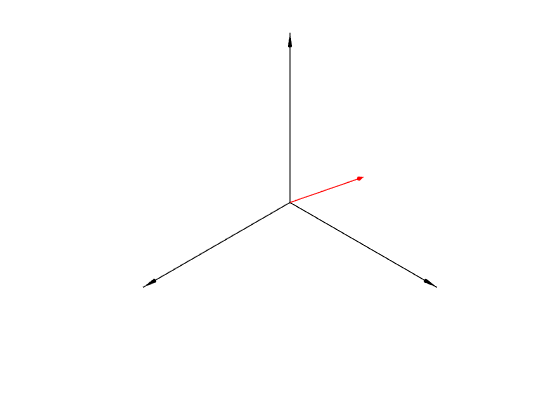

ax = axes('DataAspectRatio',[1,1,1]);
ax.XAxis.Visible = 'off';
ax.YAxis.Visible = 'off';
ax.ZAxis.Visible = 'off';
view([1,1,1]);

basis().plot; % plot the basis for reference

a = tensor([0.4;0.9;0.8]);
a.plot('color','r','facecolor','r'); 

## Symbolic objects

Objects with symbolic components have additional functionality (running this requires the Symbolic Math Toolbox installed):

syms t theta(t) phi(t); % declare symbolic variables
assume([in(t, 'real'), in(theta(t), 'real'), in(phi(t), 'real')]); 

a = tensor([cos(theta),sin(theta),0]) % a rotating vector

a = Vector with components:
 cos(theta(t))
 sin(theta(t))
             0
 

One may compute the time derivative of a symbolic object with respect to a chosen basis or reference frame with method `dt`. The result is an object of the same type. If no basis/reference frame is provided, the canonical one is assumed:

a.dt % time derivative of a in the canonical reference frame

ans = Vector with components:
 -sin(theta(t))*diff(theta(t), t)
  cos(theta(t))*diff(theta(t), t)
                                0
 


O = point([0,0,0]);
B1 = basis([1;0;0],[0;cos(phi);sin(phi)],[0;-sin(phi);cos(phi)]);
S1 = frame(O,B1);

a.dt(S1) % time derivative of a in S1

ans = Vector with components:
 -sin(theta(t))*diff(theta(t), t)
  cos(theta(t))*diff(theta(t), t)
   -sin(theta(t))*diff(phi(t), t)
 

To particularize a symbolic object at particular values of its parameters, one may use `subs`, by specifying them in a list:

a.subs({theta,t},{pi/6,0}) % replace theta with pi/6, and t with 0

ans = Vector with components:
    0.8660
    0.5000
         0
